Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# TM-mode in circular waveguide (Section 6.2)

Volker Ziemann, 211112, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

This example is very similar to TEcircular.mlx, the technical parts are almost identical, but the interpretation is different. Since we consider a TM-mode, we have to solve an eigenvalue equation, equivalent to Equation 6.2, for the longitudinal electric-field component $E_z$ instead. Let us start with the geometry definition. 

clear all; close all; 
waveguide=[1;0;0;0.1];
gd=[waveguide];         % assemble geometry
ns=char('waveguide')';  % names of the regions                 
sf='waveguide'; 
g=decsg(gd,sf,ns);
model=createpde(1);
geometryFromEdges(model,g);

Now we display the EdgeLabels to define boundary conditions, which now apply $E_z$ and have to vanish on the metallic surfaces of the waveguide; this explains the choice of Dirichlet boundary conditions. Inside the waveguide we specify `c=1` and then are ready to mesh the` model.`

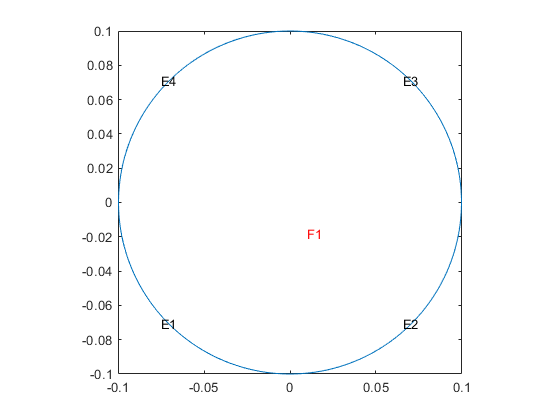

pdegplot(model,'EdgeLabels','on','SubDomainLabels','on'); axis equal

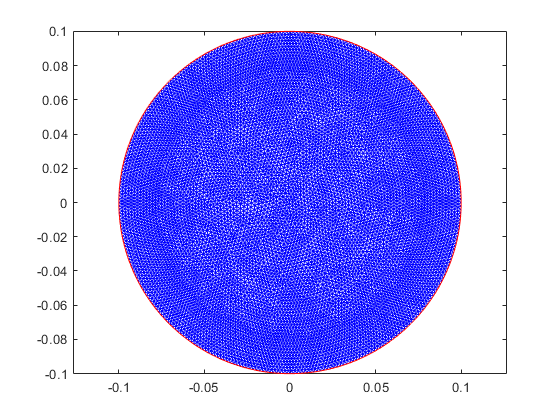

applyBoundaryCondition(model,'Edge',[1:4],'u',0); % Dirichlet
specifyCoefficients(model,'m',0,'d',1,'c',1,'a',0,'f',0,'Face',1);
generateMesh(model,'Hmax',0.002); 
figure; pdemesh(model); axis equal;

In the next step we solve the eigenvalue equation with `solvepdeeig() `and give the eigenvalues and the eigenvectors mnemonic names.

result=solvepdeeig(model,[1,2000]); 

              Basis= 10,  Time=   0.91,  New conv eig=  0
              Basis= 11,  Time=   0.95,  New conv eig=  0
              Basis= 12,  Time=   0.97,  New conv eig=  0
              Basis= 13,  Time=   0.98,  New conv eig=  1
              Basis= 14,  Time=   1.01,  New conv eig=  1
              Basis= 15,  Time=   1.03,  New conv eig=  1
              Basis= 16,  Time=   1.04,  New conv eig=  1
              Basis= 17,  Time=   1.06,  New conv eig=  1
              Basis= 18,  Time=   1.08,  New conv eig=  1
              Basis= 19,  Time=   1.10,  New conv eig=  1
              Basis= 20,  Time=   1.12,  New conv eig=  1
              Basis= 21,  Time=   1.14,  New conv eig=  2
              Basis= 22,  Time=   1.19,  New conv eig=  3
End of sweep: Basis= 22,  Time=   1.19,  New conv eig=  3
              Basis= 13,  Time=   1.38,  New conv eig=  0
End of sweep: Basis= 13,  Time=   1.38,  New conv eig=  0


eigenvalues=result.Eigenvalues; 
Ez=result.Eigenvectors;

The function `meshToPet()` returns information about the points `p`, the edges `e`, and triangles` t`, which we need to calculate the gradients with `pdegrad()`. This gives us the fields. Then we select the mode with `mymode` and plot its eigenvector Ez with `pdesurf() `and annotate the axes.

[p,e,t]=meshToPet(model.Mesh);
mymode=1;
[dEx,dEy]=pdegrad(p,t,Ez(:,mymode)); Hx=dEx; Hy=-dEy; Ex=-dEx; Ey=-dEy;
subplot(2,3,1); pdesurf(p,t,Ez(:,mymode)); axis square; view([70,30]);
xlabel('x [m]'); ylabel('y [m]'); zlabel('E_z [arb. units]')

In the following two subplots, we display the transverse electric and magnetic fields for the selected mode as arrows.

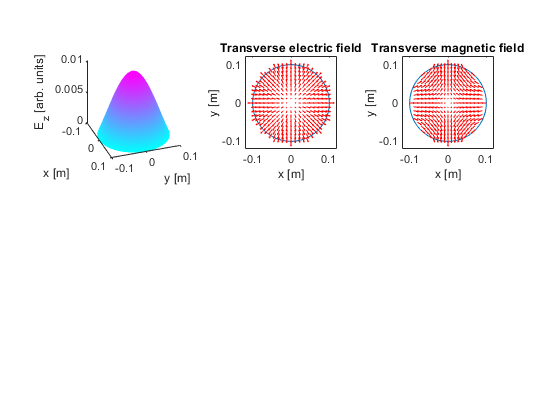

subplot(2,3,2); pdegplot(model); hold on; pdeplot(model,'flowdata',[Ex;Ey]); 
xlim([-0.12,0.12]); ylim([-0.12,0.12]); axis square; 
xlabel('x [m]'); ylabel('y [m]'); title('Transverse electric field');
subplot(2,3,3); pdegplot(model); hold on; pdeplot(model,'flowdata',[Hx;Hy]); 
xlim([-0.12,0.12]); ylim([-0.12,0.12]); axis square; 
xlabel('x [m]'); ylabel('y [m]'); title('Transverse magnetic field');